# Discrete Fourier Transform

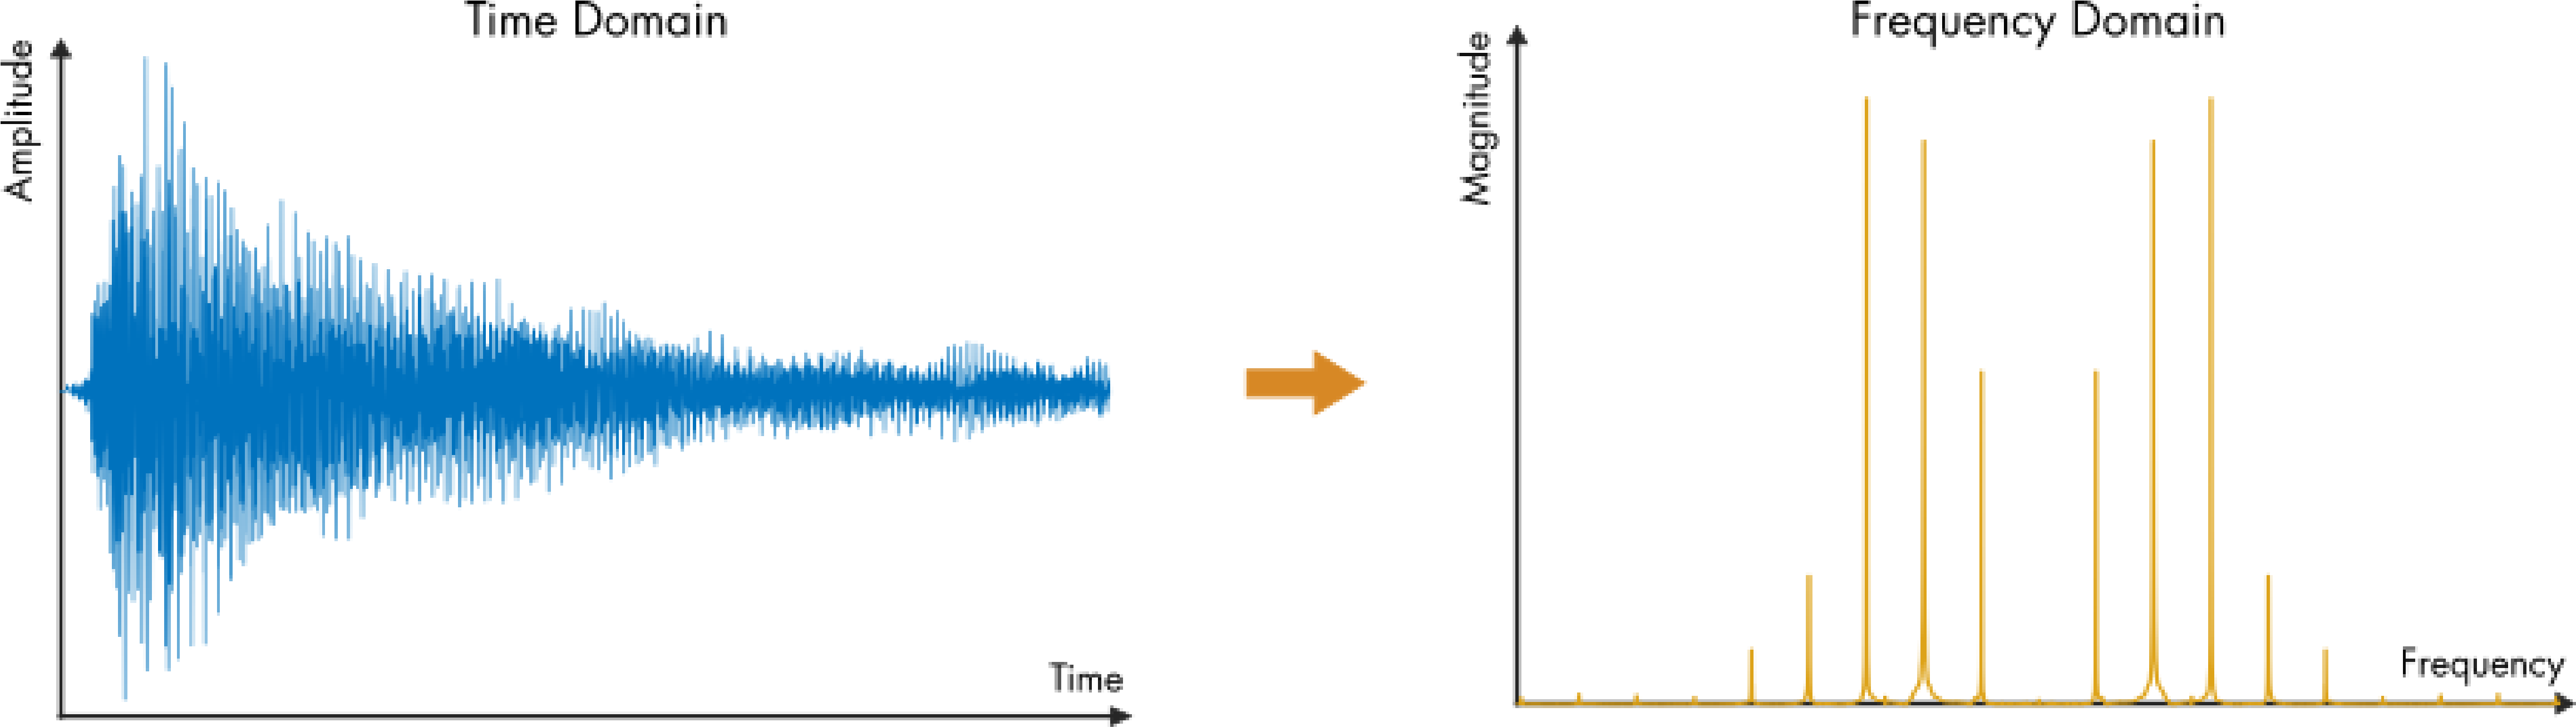

**Before you get started:**

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and they will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Introduction

The Fourier transform can be used to solve for the frequency content of an analytic function.

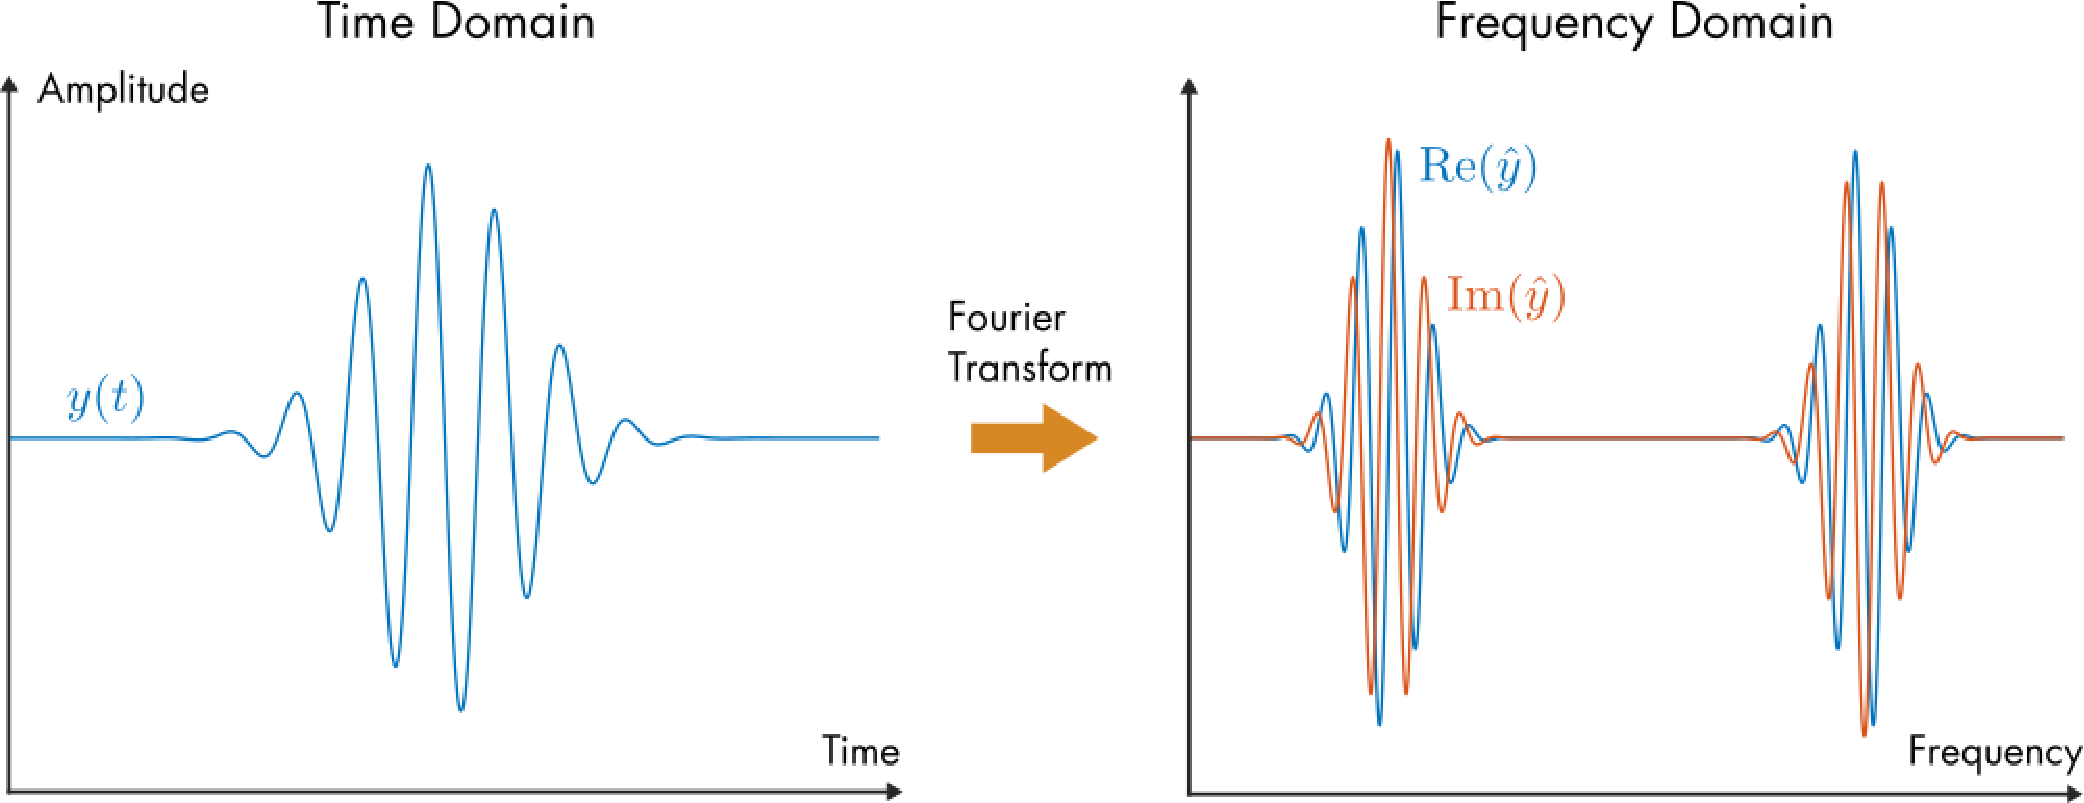

*Gaussian-modulated sinusoid in the time and frequency domains.*

However, real signals are typically discrete sequences of measured values, not analytic functions. For such signals, the Fourier transform cannot be applied directly.

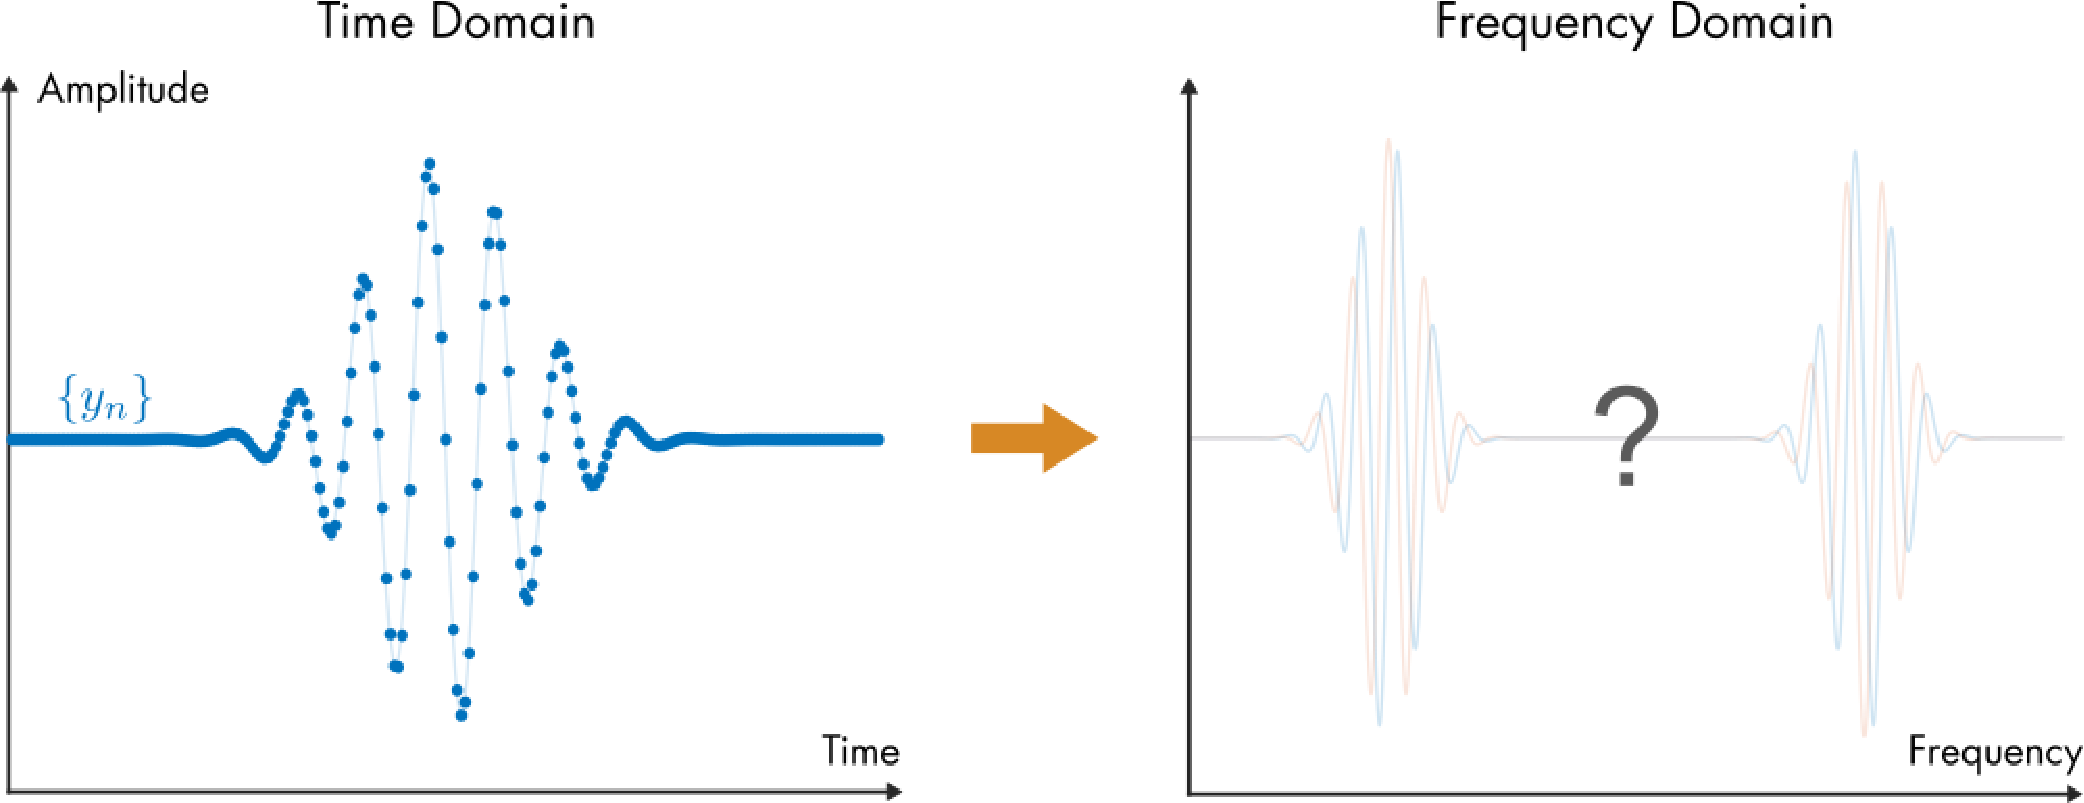

*A discrete signal *$\{ y_n \}$* sampled from an analytic function. What will it look like in the frequency domain?*

To analyze a discrete signal in the frequency domain, you can use the *Discrete Fourier Transform *(DFT). The DFT is probably the most widely used Fourier analysis tool since most real signals contain discrete measurements. You'll often find the DFT under a different name: the FFT (*Fast Fourier Transform*). Don't be confused, though; they're fundamentally the same. The FFT is simply an algorithm that computes the DFT, you guessed it, faster.

## Definition

The DFT is similar to the complex Fourier series and Fourier Transform. The essential difference is that it operates entirely in terms of discrete sequences, without any reference to continuous functions. The DFT is defined as


$$Y_k = \sum_{n = 0}^{N-1} y_n e^{- \frac{ 2 \pi i k n }{N }$$


The result is a sequence of $N$discrete values $\{ Y_k \}$ that represent $\{ y_n \}$ in the frequency domain. The result $\{ Y_k \}$ is analogous to the Fourier transform $\hat{y}(\omega)$, but more on that later.

## Computing the DFT

 **Example.** In this example, the DFT of a synthesized audio signal is computed directly from the definition.

 **Task 1.** First, create the data points by running this section.

  **Pro-tip.** To run a section quickly, use the keyboard shortcut, **Ctrl**+**Enter**.

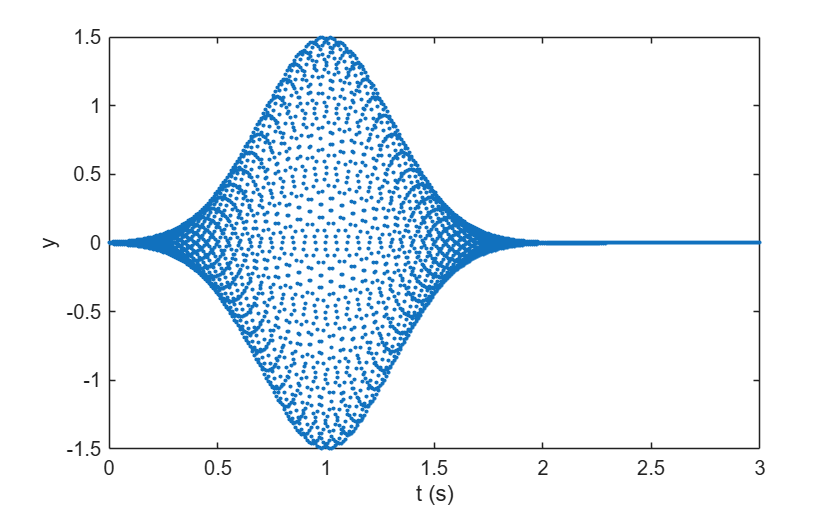

[t,y,Fs] = sineGaussData; % Helper function that generates the data is at the end of this script

figure
plot(t,y,'.')
xlabel("t (s)")
ylabel("y")

Try zooming in on the signal (use the zoom tool  ) to examine the discrete data points $y_n$ more closely. Do you see a pattern?

There is a pattern where the signal's points seem to form sinusoidal waves centered around y= 0, 0.5, 1, -0.5 and -1.

**Task 2.** Run this section to play the generated signal as an audio clip.

% This code will play the audio signal
soundsc(y,Fs)

**Task 3.** Run this section to compute the DFT using the definition. Note that the [`tic`](https://www.mathworks.com/help/matlab/ref/tic.html) and [`toc`](https://www.mathworks.com/help/matlab/ref/toc.html) functions are used to measure the time required to compute the N-point DFT.

N = numel(y); % The number of samples in y
n = 0:(N-1); % Indices
Y = zeros(N,1);
tic
% Loop through the indices of Yk
for k = 0:(N-1)
    % Compute the sum and put the result in Y
    Y(k+1) = sum( y.*exp(-2*pi*1i*k*n/N) );
end
toc

Elapsed time is 0.830352 seconds.


**Task 4.** Run this section to plot the real and imaginary components of the DFT stored in `Y`.

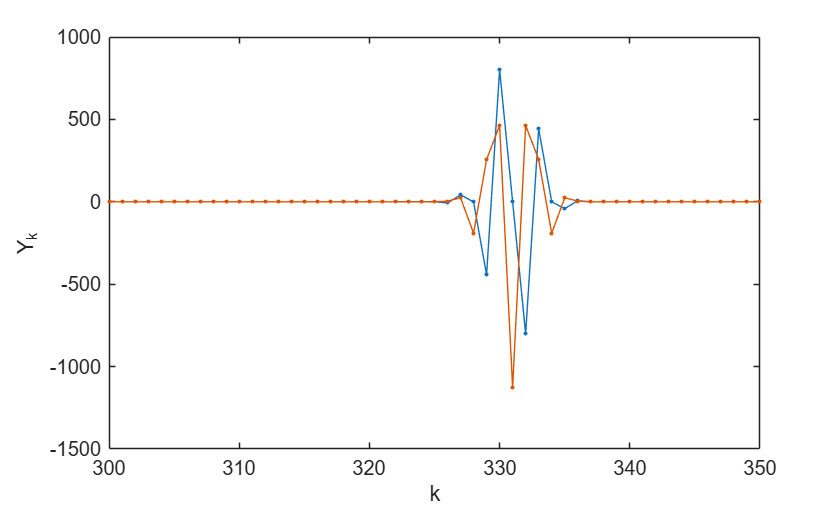

plot(real(Y),".-")
hold on
plot(imag(Y),".-")
hold off
xlabel("k")
ylabel("Y_k")
xlim([300 350])

- Try zooming in on the signal to view the DFT near the peaks. You can use the zoom tool ( ) or uncomment the line `xlim([300 350])`.

### Fast Fourier Transform (FFT)

In the previous example, the DFT was computed using a for loop, requiring $O(N^2)$ computations. The notation $O(N^2)$ means that the computational cost scales as the square of $N$ (the number of data points). This is very inefficient relative to the Fast Fourier Transform (FFT). The FFT algorithm breaks up the DFT into smaller DFTs, and then combines the results to form the full DFT. The FFT requires only $O(N \log(N))$ operations. This implies the FFT can be thousands of times faster than the DFT for large data sets.

 **Exercise.** In this exercise, you will compute the DFT using the FFT algorithm.

**Task 5.** First, create the data points by running this section.

[t,y,Fs] = sineGaussData; % Helper function that generates the data

**Task 6.** Use the [`fft`](https://www.mathworks.com/help/matlab/ref/fft.html) function to compute the DFT of `y` and store the result in Y. 

% Write your code here
tic
Y = fft(y)

Y = 1.0e+03 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


toc

Elapsed time is 0.121005 seconds.


**Task 7.** Surround the `fft` function call in **Task 2** with the [`tic`](https://www.mathworks.com/help/matlab/ref/tic.html) and [`toc`](https://www.mathworks.com/help/matlab/ref/toc.html) commands to measure how long it takes to compute the FFT. Compare this to the amount of time required using the definition in the previous section. How much faster is the FFT?

using the discrete fourier transform took `0.830352 seconds, while using the FFT algorithm took 0.121005 seconds, making it much faster than the definition in the previous section, as the FFT took only about a tenth of the time to do the transform.`

**Task 8.** Plot the real and imaginary components of `Y`. To extract the real and imaginary components, use the [`real`](https://www.mathworks.com/help/matlab/ref/real.html) and [`imag`](https://www.mathworks.com/help/matlab/ref/imag.html) functions. Use [`hold`](https://www.mathworks.com/help/matlab/ref/hold.html) commands to continue plotting on the same axes.

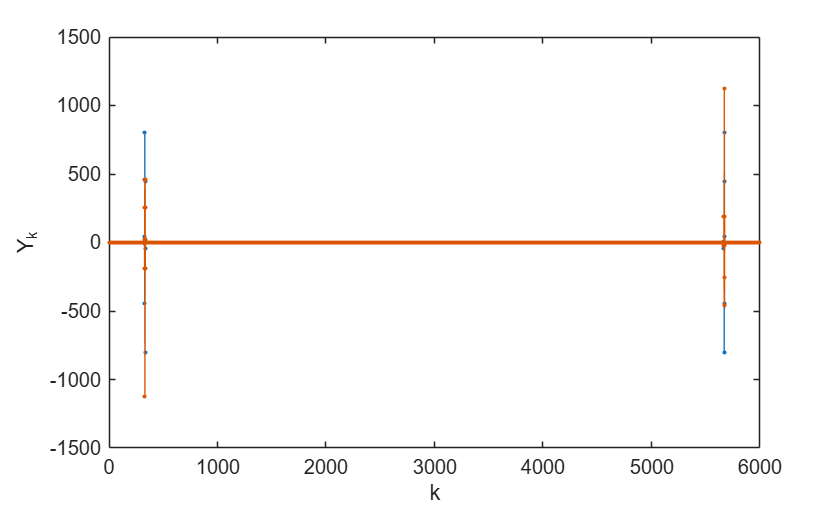

% Write your code here
plot(real(Y),".-")
hold on
plot(imag(Y),".-")
hold off
xlabel("k")
ylabel("Y_k")

%xlim([300 350])

If correct, your result should be identical to the DFT plot from the previous example.

## Comparing the DFT to the Fourier Transform

The Gaussian-modulated sinusoid is useful for comparing the DFT and Fourier transform because the analytic form is known. You probably noticed that the DFT looks similar to what you'd expect from the Fourier transform of the Gaussian-modulated sinusoid. 

The discrete data points in the previous section were sampled from a continuous function. To better understand what is computed by the DFT, it's helpful to look at the Fourier transform of the original function.

**Task 9.** Run this section to show the analytic plot. 

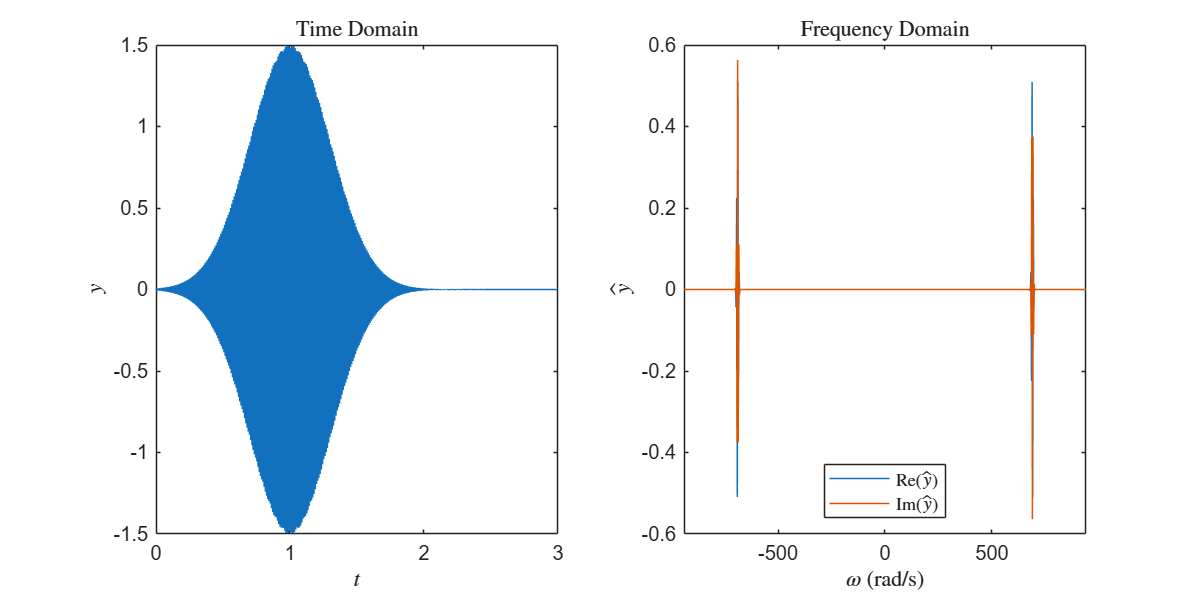

plotFourierTransform

%xlim([650 750])
 

** Reflect.** 

- Which peaks in the DFT correspond to the peaks of the Fourier transform?

- Try zooming in on the signal to view the DFT near the peaks. You can use the zoom tool ( ) or uncomment the line `xlim([650 750]).`

- How does the Fourier transform of the signal compare to the DFT?

Generally, all of the peaks in the fourier transform correspond to the peaks in the DFT. The real and imaginary peaks found in the DFT at right before k=330 to k=345 correspond the the local peaks found in the fourier transform plot at around 670 to 700 rad/s in the fourier transform. both have 4 main real peaks and 3 negative real peak along with 3 imaginary peaks and 3 negative imaginary peaks.

However, in the DFT, due to the sampling only taking specific points, some of the peaks are smaller in relative magnitude than they would otherwise be if taken in continuous time. the  peaks in the DFT are less pronounced and are "wider" compared to the fourier transform. However, both generally are the same,  but the magnitude of the DFT needs to be scaled to properly compare the magnitudes with the fourier transform.

Also, while the fourier transform is in radians, the DFT is indexed by k instead. Additionally, the DFT doesn't capture the peaks and -500rad/s, and it only captures that section when the function repeats itself later on in the next period. (i.e.: the first peak in the DFT corresponds to the second one in the fourier transform).

To understand the differences between the Fourier transform and the DFT plots, compare the DFT and Fourier transform definitions. The DFT:


$$Y_k = \sum_{n = 0}^{N-1} y_n e^{- \frac{ 2 \pi i k n }{N }$$


The Fourier transform:


$$\hat{y}(\omega) = \int_{-\infty}^\infty y(t) e^{-i\omega t} \ dt$$


Notice the similarities:

- The DFT sum approximates the integral

- The two factors correspond between definitions $ y_n \leftrightarrow y(t)$ and $e^{- \frac{ 2 \pi i k n }{N }} \leftrightarrow  e^{-i\omega t} $. 

Notice two essential differences:

- The $dt$ of the integral scales the Fourier transform $\hat{y}$, but the DFT result, $Y_k$, is not scaled by a $\Delta t$.

- The complex exponential is given in terms of discrete indices: $k$ and $n$, rather than continuous variables, $\omega$ and $t$.

 **Example.** In the example, the DFT will be related to the Fourier transform using the Gaussian-modulated sinusoid.

**Task 10.** Run this section to compute the DFT using the [`fft`](https://www.mathworks.com/help/matlab/ref/fft.html) function.

[t,y,Fs] = sineGaussData; % Helper function that generates the data
Y = fft(y);

The Fourier transform is scaled (in amplitude) by $dt$. The discrete analog of $dt$ is the time step $\Delta t$ in the sampled signal. The time step $\Delta t = 1/ f_s$, where $f_s$ is the sampling frequency. This implies that, to rescale the output $Y$ to match $\hat{y}$, you can multiply by `1/Fs`.**Task 1.** Run this section to rescale `Y` and plot the result. 

**Task 11.** Compare the vertical axis scale to the result of the analytic Fourier transform.

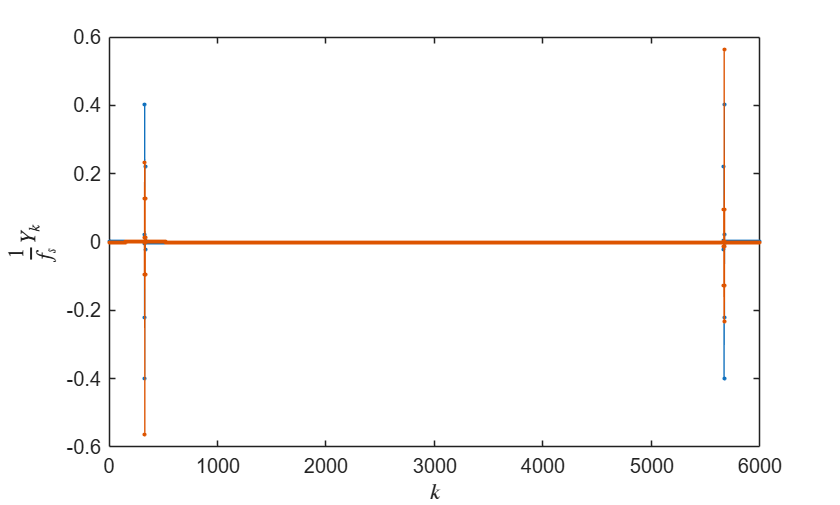

N = length(Y);
k = 0:(N-1);
Yrescaled = 1/Fs*Y;
realImagPlot(k,Yrescaled,"$k$","$\frac{1}{f_s}Y_k$"); % Helper function that creates the plot

The plot of the DFT now has approximately the same magnitudes as the Fourier transform

You can also use the sample rate $f_s$ to relate the discrete indices $k$ and $n$ to the continuous variables $\omega$ and $t$. Equating these terms in the exponentials of each definition:


$$  \frac{2 \pi kn}{N} = t \omega$$


Discretizing $t$ as $n \Delta t  = n / f_s$ implies that the discrete frequencies are


$$\omega_k = \frac{ 2 \pi k f_s}{   N}$$


**Task 12.** Run this section to plot the DFT result against the angular frequencies $\omega_k$.

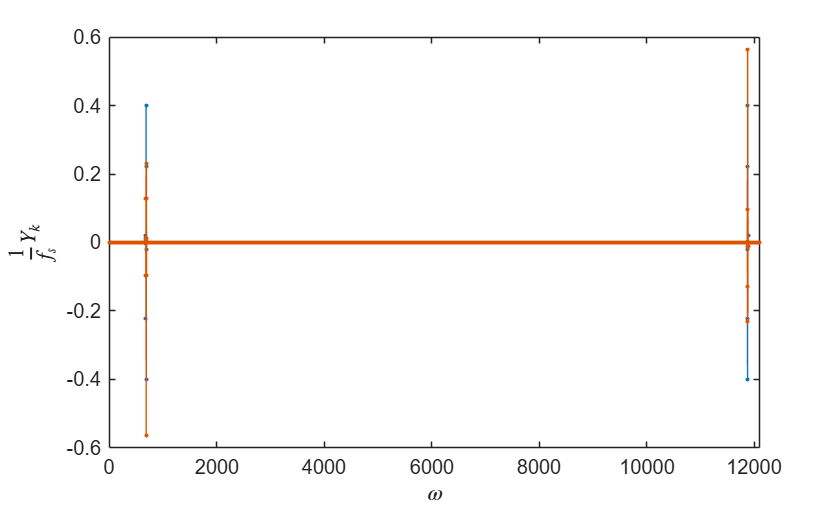

omega = 2*pi*k*Fs/N;
realImagPlot(omega,Yrescaled,"$\omega$","$\frac{1}{f_s}Y_k$"); % Helper function that creates the plot

Compare the angular frequencies of the DFT along the $\omega$-axis to those of the Fourier transform. Are the peaks in the same location? You can identify the locations of the peaks by clicking on the graph to create a tooltip. 

You should notice that the **first **peak of the DFT matches the **second** peak of the Fourier transform. This results from the definition of the DFT (which has unexpected consequences). You can use the [`fftshift`](https://www.mathworks.com/help/matlab/ref/fftshift.html) function to get the DFT lined up with the Fourier transform.

**Task 13.** Run this section to rearrange the DFT values, $\{ Y_k \}$, so that they line up with the Fourier transform $\hat{y}$ . The values of $\omega$ are also regenerated to correspond to the shifted frequencies.

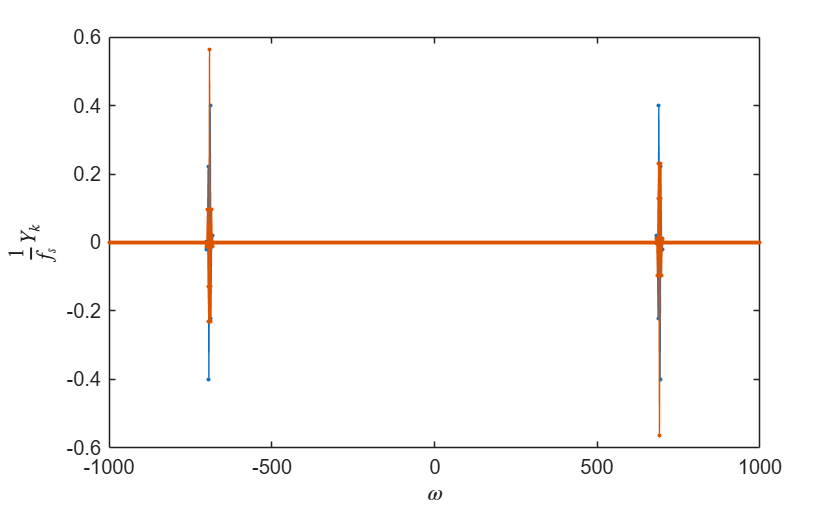

% Shift the Y-values
Yshift = fftshift(Yrescaled);
% Shift the angular frequency
omegaShift = 2*pi*Fs/N*(-N/2:N/2-1);

realImagPlot(omegaShift,Yshift,"$\omega$","$\frac{1}{f_s}Y_k$"); % Helper function that creates the plot
xlim([-1000 1000])

**Task 14.** Run this section to plot the shifted DFT values (`Yshift)` alongside the Fourier transform.

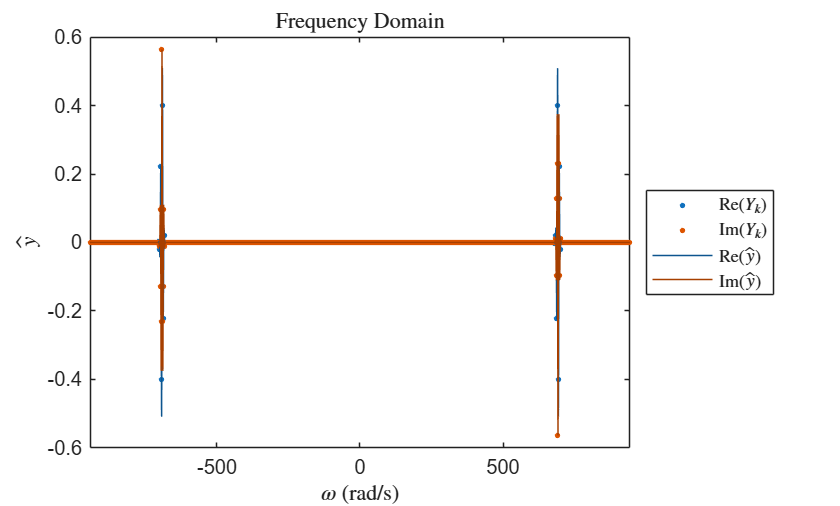

plotDFTandTransform(omegaShift,Yshift);

% xlim([650,750])

- Try zooming in on the signal to view the DFT near the peaks. You can use the zoom tool ( ) or uncomment the `xlim([650,750])` line.

## Analyzing an Audio Signal

The FFT is commonly used to analyze the frequency domain content of measured signals. This is one of the essential methods in signal processing.

 **Exercise.** In this exercise, you will analyze the frequencies present in a guitar note.

**Task 15.** Run this section to read the MP3 and plot the signal. The signal content (Anote.mp3) should be stored in the current director.

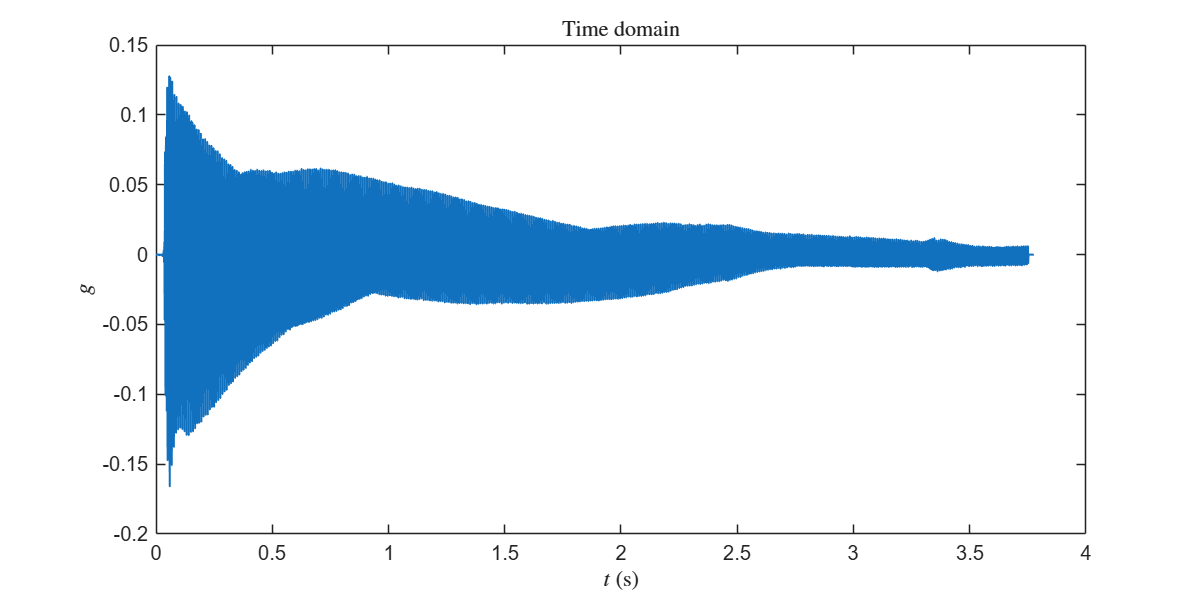

% This code plays the guitar sound and plots part of the signal
[g2Ch,Fs] = audioread("Anote.mp3");
g = g2Ch(:,1); % Only use the first audio channel
soundsc(g,Fs)
plotGuitarSignal(g,Fs)

- Try zooming in on the signal ( ) to view the time-domain content.

**Task 16.** Run this section to compute the DFT using the definition similar to what you did for the previous example. Do you get an error message? 

% Write your code here
N = numel(g); % The number of samples in g
n = 0:(N-1); % Indices
G = zeros(N,1);
tic
% Loop through the indices of Gk
for k = 0:(N-1)
    % Compute the sum and put the result in Y
    G(k+1) = sum( g.*exp(-2*pi*1i*k*n/N) );
end

Requested 166512x166512 (206.6GB) array exceeds maximum array size preference (7.7GB) and might cause MATLAB to become unresponsive.

Related documentation

toc

Yes, I did get an error message. It displayed as "`Requested 166512x166512 (206.6GB) array exceeds maximum array size preference (7.7GB) and might cause MATLAB to become unresponsive." T`his indicates it ran out of memory to process this DFT using the definition as it is simply too much to compute.

**Task 17.** Compute the DFT of the signal `g` using [`fft`](https://www.mathworks.com/help/matlab/ref/fft.html). Store the result in `G`.

% Write your code here
G = fft(g) 

G = 1.0e+03 *

   0.0102 + 0.0000i
  -0.0002 + 0.0000i
  -0.0003 + 0.0000i
  -0.0001 + 0.0001i
  -0.0001 + 0.0001i
  -0.0001 + 0.0000i
  -0.0001 + 0.0000i
  -0.0001 + 0.0002i
  -0.0002 + 0.0003i
  -0.0000 + 0.0001i
  -0.0000 + 0.0002i
  -0.0000 + 0.0003i
  -0.0000 + 0.0001i
  -0.0001 + 0.0003i
  -0.0001 + 0.0002i


**Task 18.** Rescale `G` by multiplying it by `1/Fs` (`Fs` contains the sampling frequency). This relates the vertical axis of `G` to the Fourier transform. Store the result in `Gscaled`.

% Write your code here
Gscaled = G * (1/Fs)

Gscaled =    0.0002 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i


**Task 19.** The result of FFT makes more sense after the "high frequency content" is shifted to negative frequencies. Use [`fftshift`](https://www.mathworks.com/help/matlab/ref/fftshift.html) to perform this operation on `Gscaled` and store the result in `Gshift`.

% Write your code here
Gshift = fftshift(Gscaled)

Gshift =    0.0000 + 0.0000i
  -0.0000 - 0.0000i
  -0.0000 + 0.0000i
   0.0000 - 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 - 0.0000i
   0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 - 0.0000i
   0.0000 - 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


**Task 20.** Compute the angular frequencies (Omega) that correspond to `GShift` and store them in a vector `omega`. The angular frequencies (in rad/s) that correspond to the result of `fftshift` are


$$\omega_k = \frac{ 2 \pi k f_s}{   N}$$
 

where $f_s$ is the sampling frequency, $N$ is the number of samples, and $k$ ranges from $-N/2$ to $N/2-1$.

**Hint**: start by computing the length of the signal `g` and storing the result in `N`. The sampling frequency is already stored in the variable `Fs`.

% Write your code here
 N = numel(g)

N = 166512

 k = (-N/2:N/2-1)

k =       -83256      -83255      -83254      -83253      -83252      -83251      -83250      -83249      -83248      -83247      -83246      -83245      -83244      -83243      -83242      -83241      -83240      -83239      -83238      -83237      -83236      -83235      -83234      -83233      -83232      -83231      -83230      -83229      -83228      -83227      -83226      -83225      -83224      -83223      -83222      -83221      -83220      -83219      -83218      -83217      -83216      -83215      -83214      -83213      -83212      -83211      -83210      -83209      -83208      -83207


omega = 2*pi*k*Fs/N

omega = 1.0e+05 *

   -1.3854   -1.3854   -1.3854   -1.3854   -1.3854   -1.3854   -1.3853   -1.3853   -1.3853   -1.3853   -1.3853   -1.3853   -1.3852   -1.3852   -1.3852   -1.3852   -1.3852   -1.3852   -1.3851   -1.3851   -1.3851   -1.3851   -1.3851   -1.3851   -1.3850   -1.3850   -1.3850   -1.3850   -1.3850   -1.3850   -1.3849   -1.3849   -1.3849   -1.3849   -1.3849   -1.3849   -1.3848   -1.3848   -1.3848   -1.3848   -1.3848   -1.3848   -1.3847   -1.3847   -1.3847   -1.3847   -1.3847   -1.3847   -1.3846   -1.3846


**Task 21.** Plot the real and imaginary components of `Gshift` against `omega`. 

**Hint**: To extract the real and imaginary components, use the [`real`](https://www.mathworks.com/help/matlab/ref/real.html) and [`imag`](https://www.mathworks.com/help/matlab/ref/imag.html) functions. Use [`hold`](https://www.mathworks.com/help/matlab/ref/hold.html) commands to continue plotting on the same axes.

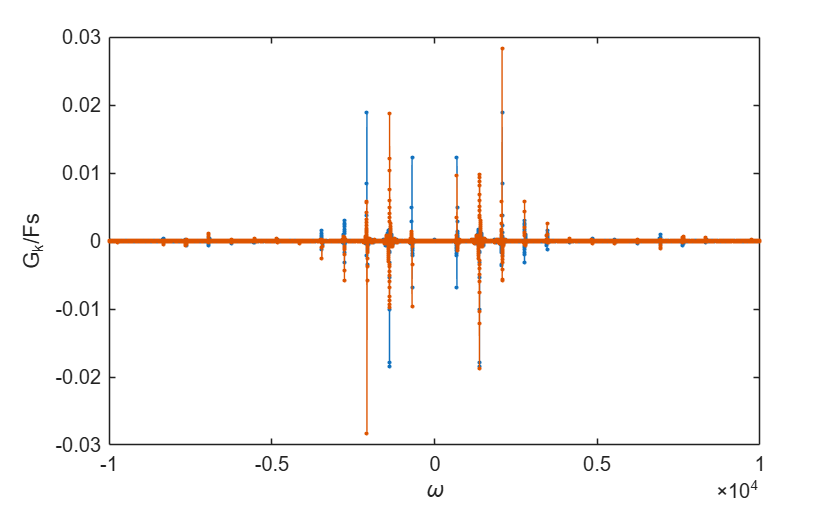

figure % Create a new figure
% Write your code here
plot(omega,real(Gshift),".-")
hold on
plot(omega,imag(Gshift),".-")
hold off
xlabel("\omega")
ylabel("G_k/Fs")
xlim([-10^4,10^4])

Zoom in on the plot (using the zoom tool   or [`xlim`](https://www.mathworks.com/help/matlab/ref/xlim.html)). If your calculations are correct, you should see this plot:

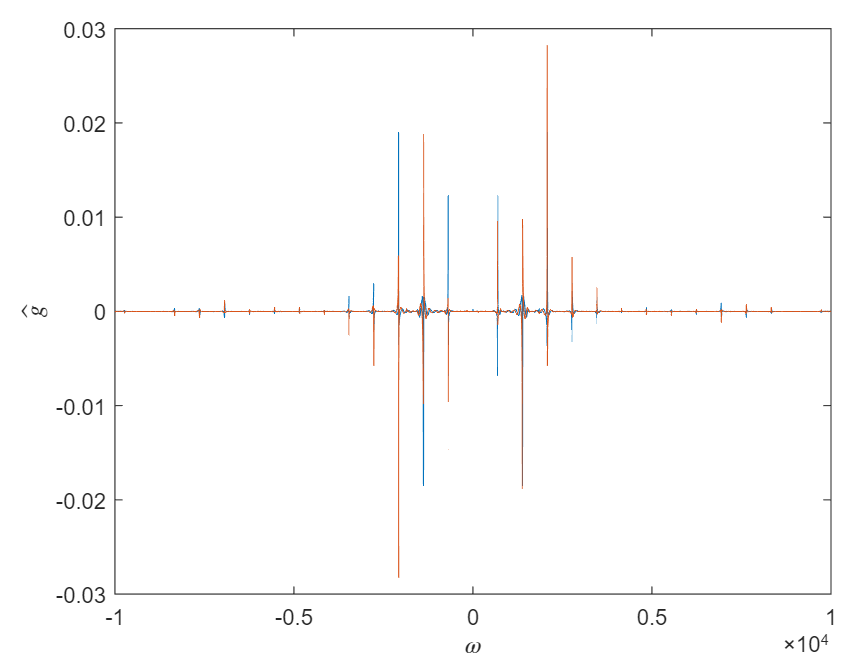

Instead of looking at the real and imaginary components of $G$, it's often more helpful to look at the magnitude.

**Task 22.** Compute the magnitude of `Gshift` using [`abs`](https://www.mathworks.com/help/matlab/ref/abs.html). Store the result in `Gabs`. Then, plot `Gabs` against `omega`.

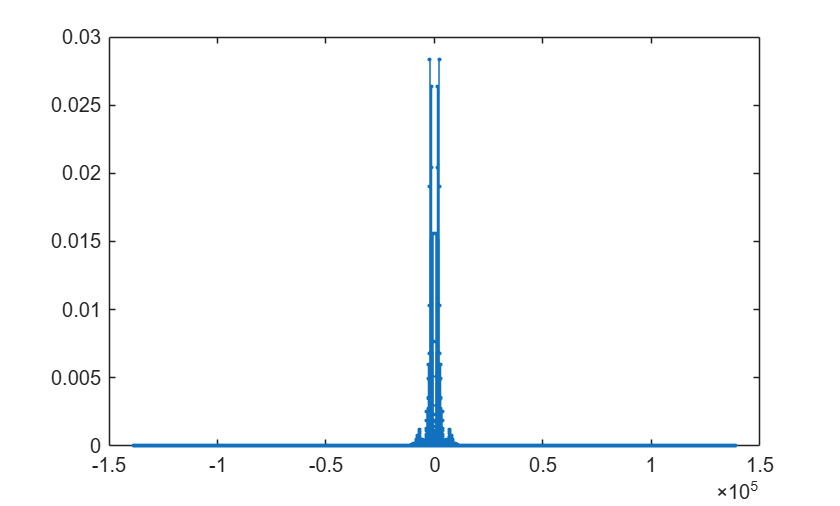

% Write your code here
Gabs = abs(Gshift);
plot(omega, Gabs, ".-")

**Task 23.** Plotting against the angular frequency $\omega$ (given in rad/s) is useful for comparing to the Fourier transform, but less so for understanding real signals. 

- Compute the frequencies in Hz from `omega` and store the result in `freq`. 

- Plot `Gabs` against `freq`.

- Much of the frequency content is between -600 Hz and 600 Hz, so adjust the axis limits to that range.

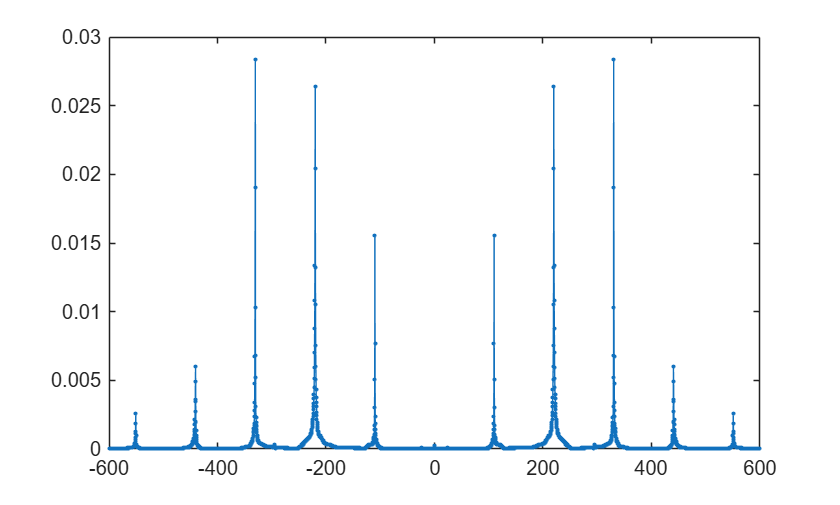

% Write your code here
freq = omega/(2*pi);
plot(freq,Gabs,".-")
xlim([-600,600])

**Task 24.** Find the location and thhe frequency of the peaks using [findpeaks](https://www.mathworks.com/help/signal/ref/findpeaks.html) function. Use this function to find the top 8 peaks adding the following options 

*'NPeaks',8, SortStr="descend"*

Then, extract the frequecies of the peaks

% Write your code here
[peaks, frequencies] = findpeaks(Gabs,'NPeaks',8,SortStr="descend");
peak_freqs = freq(frequencies)%convert to Hz

peak_freqs =  -330.2627  330.2627 -219.8220  219.8220 -109.9110  109.9110 -440.4385  440.4385


peaks

peaks =     0.0283
    0.0283
    0.0264
    0.0264
    0.0156
    0.0156
    0.0060
    0.0060


**Task 25.** This signal came from a single guitar string being plucked. Which string did it come from (low E, A, D, G, B, high E)? Record your answer in the space below.

**Hints:**

- Recall that a single string will vibrate with a fundamental frequency and several harmonics.

- You can click a peak in the frequency domain to create a tooltip.

- A table of some of the relevant notes is shown below.

            
$$\text{\textbf{Octave 2}}
\\
\begin{array}{lr} 
\text{Note} & \text{ Hz} \\
C & 65.4 \\ 
C\# & 69.3 \\
D & 73.4 \\
D\# & 77.8\\
E & 82.4\\
F & 87.3 \\
F\# & 92.5 \\
G & 98.0\\
G\# & 103.8\\
A & 110.0\\
A\# & 116.5\\
B & 123.5\\
\end{array}$$
                
$$\text{\textbf{Octave 3}}
\\
\begin{array}{lr} 
\text{Note} & \text{ Hz} \\
C & 130.8 \\ 
C\# & 138.6 \\
D & 146.8\\
D\# & 155.6\\
E & 164.8\\
F & 174.6 \\
F\# & 185.0 \\
G & 196.0\\
G\# & 207.7\\
A & 220.0\\
A\# & 233.1\\
B & 246.9\\
\end{array}$$
                
$$\text{\textbf{Octave 4}}
\\
\begin{array}{lr} 
\text{Note} & \text{ Hz} \\
C & 261.6 \\ 
C\# & 277.2 \\
D & 293.7\\
D\# & 311.1\\
E & 329.6\\
F & 349.2\\
F\# & 370.0\\
G & 392.0\\
G\# & 415.3\\
A & 440.0\\
A\# & 466.2\\
B & 493.9\\
\end{array}$$


% Record your answer (E, A, D, G, or B) in the quotes
note = "A";

**Task 26.** Reflect on the knowledge and skills you have gained through completing this assignment. Highlight the specific concepts or techniques you have learned, the challenges you encountered, and how you overcame them. Discuss how this experience has enhanced your understanding of the subject matter and contributed to your personal or professional growth. Conclude by emphasizing the value of the assignment in building your confidence and preparing you for future tasks or projects.

**Your Answer:**

I have learned how to perform a DFT and FFT along with the understanding that an FFT is functionally the same as using the definition of DFT, but with a far smaller computational load (O(N/2logbase2(N)) rather than the O(N^2) it would have taken with definition), allowing it to better deal with longer sequences and more information in a signal. 

I have also learned that in order to make the DFT or FFT resemble the continuous equivalent, I must first rescale the magnitude of the discretely transformed signal by dividing it by its sampling frequency, then I must rescale its index back into the radian equivalent by plotting the transformed signal with omega = 2*pi*Fs*k/N*, and realigning the signal by running it through fftshift() to make the peaks correspond with the continuous time equivalents, allowing me to compare the two.

The main challenges that I encountered were mostly trying to interpret the DFT and FFT signal before they were scaled to the continuous time equivalent, as I did not initially know that they needed to be scaled, which caused some confusion that was resolved as I went further down the document.

This experience has given me first hand knowledge in the computational complexity differences between DFT and FFT, along with teaching me how to perform the fft() algorithm on a discrete signal and how to rescale it for comparison and interpretation through the use of an audio signal processing example of a plucked guitar note. This will allow me to perform similar analyses on future signals I may encounter in the workplace or in future coursework.

In conclusion, this assignment's use of a practical example and theoretical explanations of what is happening has allowed me to understand not only how to perform and rescale fast fourier transforms in MATLAB, but also how to apply this concept in any other number of contexts and situations, building my confidence in future tasks and projects.

**Helper Functions**

function [t,y,Fs,A,c,t0,omega0,tLims,N] = sineGaussData
    % Sample a Gaussian-modulated sinusoid

    Fs = 2e3; % Audio sample rate

    % Gaussian-modulated sine data
    A = 1.5; % Amplitude
    f0 = 110; % Carrier frequency (Hz)
    c = 0.3; % Gaussian "width"
    t0 = 1; % Center position (s)
    omega0 = f0*2*pi; % Angular frequency (rad/s)

    % Discretize
    tLims = [0 3];
    N = round(Fs*(tLims(2)-tLims(1)));
    t = (0:1/Fs:N/Fs-1/Fs) + tLims(1);
    y = A*sin(omega0*t).*exp(-(t-t0).^2/(2*c^2));
end

%%%%%%%%
function plotFourierTransform
    % Plot the Fourier transform of the Gaussian-modulated sinusoid

    % The function data
    [t,y,Fs,A,c,t0,omega0,tLims,N] = sineGaussData;

    % Plot parameters
    omegaLims = 2*pi*[-150 150];

    % Compute transform
    omega = linspace(omegaLims(1),omegaLims(2),2e4);
    yhat = -A*sqrt(pi/2)*1i*c.*(exp(-0.5*(omega-omega0).*(c^2*omega-c^2*omega0+2*t0*1i)) - ...
        exp(-0.5*(omega+omega0).*(c^2*omega+c^2*omega0+2*t0*1i)));

    % Create plots
    figure("Position",[1 1 800 400])
    subplot(1,2,1)
    plot(t,y)
    xlim(tLims)
    xlabel("$t$","Interpreter","latex")
    ylabel("$y$","Interpreter","latex")
    title("Time Domain","Interpreter","latex")

    subplot(1,2,2)
    plot(omega,real(yhat))
    hold on
    plot(omega,imag(yhat))
    hold off
    xlim([omega(1),omega(end)])
    xlabel("$\omega$ (rad/s)","Interpreter","latex")
    ylabel("$\hat{y}$","Interpreter","latex")
    legend("Re$(\hat{y})$","Im$(\hat{y})$","Interpreter","latex","Location","south");
    title("Frequency Domain","Interpreter","latex")

end

%%%%%%%%
function realImagPlot(x,y,xLabel,yLabel)
    % Create complex plot with the given labels
    
    figure
    plot(x,real(y),".-")
    hold on
    plot(x,imag(y),".-")
    hold off
    xlabel(xLabel,"Interpreter","latex")
    ylabel(yLabel,"Interpreter","latex")
end

%%%%%%%%
function plotDFTandTransform(omegaShift, Yshift)
    % Plot the DFT in Yshift and the Fourier 
    % transform of the Gaussian-modulated sinusoid
    
    colors = lines(2);

    % Plot the DFT
    figure
    plot(omegaShift,real(Yshift),".","MarkerSize",8)
    hold on
    plot(omegaShift,imag(Yshift),".","MarkerSize",8)
    hold off

    % Compute transform and plot it
    [t,y,Fs,A,c,t0,omega0,tLims,N] = sineGaussData;
    % Plot parameters
    omegaLims = 2*pi*[-150 150];
    % Compute transform
    omega = linspace(omegaLims(1),omegaLims(2),2e4);
    yhat = -A*sqrt(pi/2)*1i*c.*(exp(-0.5*(omega-omega0).*(c^2*omega-c^2*omega0+2*t0*1i)) - ...
        exp(-0.5*(omega+omega0).*(c^2*omega+c^2*omega0+2*t0*1i)));
    
    hold on
    plot(omega,real(yhat),"color",colors(1,:)*0.75)
    plot(omega,imag(yhat),"color",colors(2,:)*0.75)
    hold off
    xlim([omega(1),omega(end)])
    xlabel("$\omega$ (rad/s)","Interpreter","latex")
    ylabel("$\hat{y}$","Interpreter","latex")
    legend("Re$(Y_k)$","Im$(Y_k)$",...
           "Re$(\hat{y})$","Im$(\hat{y})$",...
           "Interpreter","latex","Location","eastoutside");
    title("Frequency Domain","Interpreter","latex")
end

%%%%%%%%
function plotGuitarSignal(yGuitar,FsGuitar)
    % Plot the guitar signal in the time domain

    tGuitar = (1:length(yGuitar))/FsGuitar; % Time variable    
    % Generate the plot
    figure("position",[1,1,800,400]) 
    plot(tGuitar,yGuitar(:,1),"Linewidth",1)
    xlabel("$t$ (s)","Interpreter","latex")
    ylabel("$g$","Interpreter","latex")
    title("Time domain","Interpreter","latex")
    end